%---------------DEEP LEARNING-------------------

                         MOVE CURRENT DIRECTORY WHERE DATA TRAINING FILES ARE THERE

DESKTOP >   MATLAB_DATA_FILES ----->DEEP_LEARNING_FILES------>DEEP_LEARNING_FILES

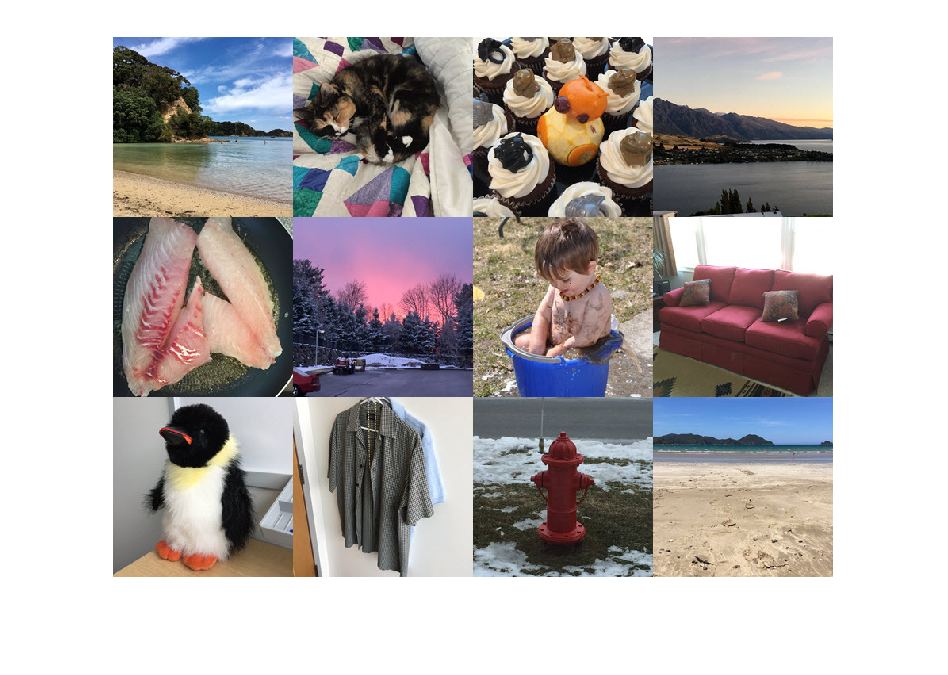

flowers_ds=imageDatastore("Flowers\","IncludeSubfolders",true,"LabelSource","foldernames");
random_ds=imageDatastore("RandomImages\");
roundworm_ds=imageDatastore("Roundworms\","IncludeSubfolders",true);
%include subfolder is used  to include subfolders which holds sub images
montage(random_ds)

% imageprepricessing
new_datastore=augmentedImageDatastore([224 224],random_ds);
imread("Flowers\bluebell\image_0241.jpg");

figure
subplot(4,3,1)                  %subplot(row,column,plot_no)
x=1:5:3

x = 1

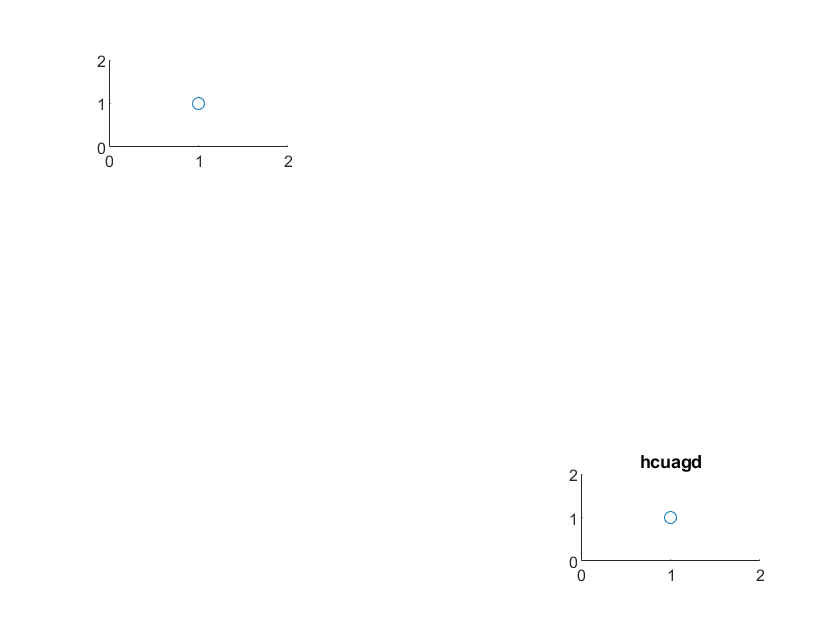

scatter(x,x^2);
subplot(4,3,12)
scatter(x,x.^3)
title("hcuagd")

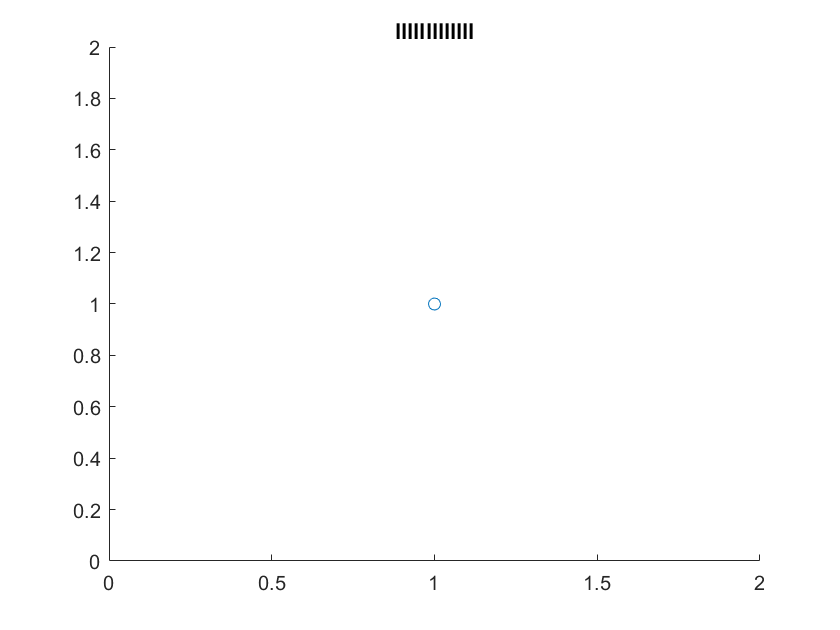

figure
scatter(x,x.^5);
title("lllllllllllll")

PRETRAINED NETWORK: GOOGLENET                                              TRANSFER LARANING

flowers_ds=imageDatastore("Flowers\","IncludeSubfolders",true,"LabelSource","foldernames");
[train test]=splitEachLabel(flowers_ds,0.6)          %60 is train data and 40% is test data

train =   ImageDatastore with properties:

                       Files: {
                              ' ...\deeplearning_course_files\Flowers\bluebell\image_0241.jpg';
                              ' ...\deeplearning_course_files\Flowers\bluebell\image_0242.jpg';
                              ' ...\deeplearning_course_files\Flowers\bluebell\image_0243.jpg'
                               ... and 573 more
                              }
                     Folders: {
                              ' ...\deeplearning_course_files\deeplearning_course_files\Flowers'
                              }
                      Labels: [bluebell; bluebell; bluebell ... and 573 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readData

test =   ImageDatastore with properties:

                       Files: {
                              ' ...\deeplearning_course_files\Flowers\bluebell\image_0289.jpg';
                              ' ...\deeplearning_course_files\Flowers\bluebell\image_0290.jpg';
                              ' ...\deeplearning_course_files\Flowers\bluebell\image_0291.jpg'
                               ... and 381 more
                              }
                     Folders: {
                              ' ...\deeplearning_course_files\deeplearning_course_files\Flowers'
                              }
                      Labels: [bluebell; bluebell; bluebell ... and 381 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatas

model=googlenet

model =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


train_new_pixel=augmentedImageDatastore([224,224],train);
test_new_pixel=augmentedImageDatastore([224,224],test);
layers=model.Layers

layers =   144×1 Layer array with layers:

     1   'data'                           Image Input                   224×224×3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2'                   Convolution                   64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU                          ReLU
     4   'pool1-3x3_s2'                   Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1'                    Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce'               Convolution                   64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU                          ReLU
     8   'conv2-3x3'                      Convolution               

layers(144).Classes

ans = 1000×1 categorical array
     tench 
     goldfish 
     great white shark 
     tiger shark 
     hammerhead 
     electric ray 
     stingray 
     cock 
     hen 
     ostrich 
     brambling 
     goldfinch 
     house finch 
     junco 
     indigo bunting 
     robin 
     bulbul 
     jay 
     magpie 
     chickadee 
     water ouzel 
     kite 
     bald eagle 
     vulture 
     great grey owl 
     European fire salamander 
     common newt 
     eft 
     spotted salamander 
     axolotl 


layers_arch=layerGraph(model);
layer_cntd=fullyConnectedLayer(12,"Name","connected1");
layer_classfcn=classificationLayer("Name","clsfcn_lyr1");
layers_arch=replaceLayer(layers_arch,"loss3-classifier",layer_cntd)

layers_arch =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


layers_arch=replaceLayer(layers_arch,"output",layer_classfcn)      %layers_arch=replaceLayer(mode,"old_clsfcn_lyr",layer_classfcn)

layers_arch =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'clsfcn_lyr1'}


opt_algorithm=trainingOptions("sgdm","InitialLearnRate",0.5,"Plots","training-progress","MaxEpochs",8)

opt_algorithm =   TrainingOptionsSGDM with properties:

                    Momentum: 0.9000
            InitialLearnRate: 0.5000
           LearnRateSchedule: 'none'
         LearnRateDropFactor: 0.1000
         LearnRateDropPeriod: 10
            L2Regularization: 1.0000e-04
     GradientThresholdMethod: 'l2norm'
           GradientThreshold: Inf
                   MaxEpochs: 8
               MiniBatchSize: 128
                     Verbose: 1
            VerboseFrequency: 50
              ValidationData: []
         ValidationFrequency: 50
          ValidationPatience: Inf
                     Shuffle: 'once'
              CheckpointPath: ''
        ExecutionEnvironment: 'auto'
                  WorkerLoad: []
                   OutputFcn: []
                       Plots: 'training-progress'
              SequenceLength: 'longest'
        SequencePaddingValue: 0
    SequencePaddingDirection: 'right'


%predctn=classify(network,test_new_pixel)
layers_arch.Layers(142)

ans =   FullyConnectedLayer with properties:

          Name: 'connected1'

   Hyperparameters
     InputSize: 'auto'
    OutputSize: 12

   Learnable Parameters
       Weights: []
          Bias: []

  Show all properties


layers_arch.Layers(144).Classes

ans = 'auto'

a=[1 2 5 4];
b=[8 2 6 4];
c=nnz(a==b)

c = 2

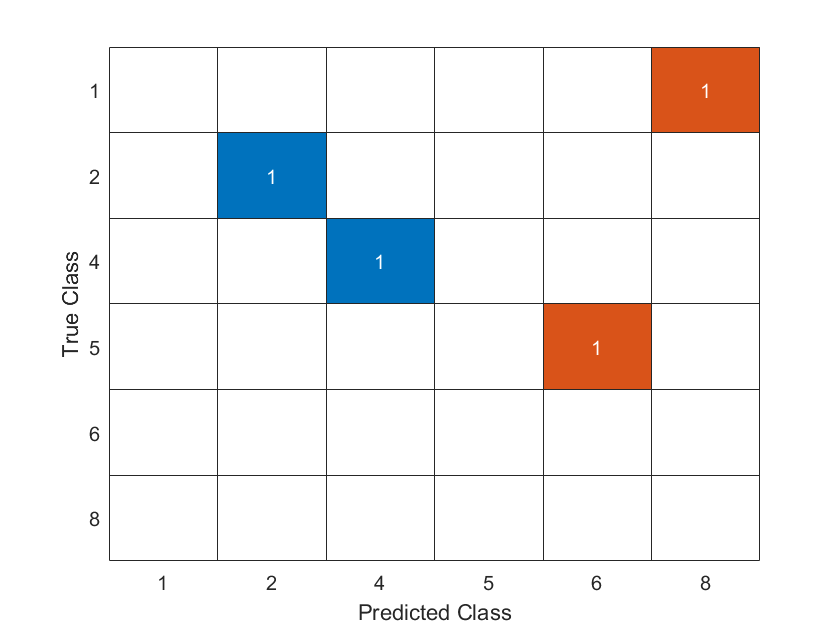

confusionchart(a,b)

% readimage(datastore,image_index)
image=readimage(flowers_ds,5)

image = 224×224×3 uint8 array
image(:,:,1) =

   189   199   206   212   226   243   250   242   243   119    14    20    35    18    17    11    14     4    31    46    44    46    56    86   120   123   117    84    61    92   120   109   111    74    25     2     4     6    14    30    31    29    26    39    42    43    72    93   123   189   237   225   194   168   122    73    84    98    99   121   151   136   137   193   194   211   207   187   207   181   100    82    89    94   146   166   156   129    88    79    82    58    74   120   172   182   171   191   182   168   174   195   195   195   207   185   184   188   192   190   191   190   182   175   127    99   106   156   192   189   179   187   209   205   199   200   204   203   193   184   183   188   178   167   140    75    55    91   149   178   200   166    67    52   142   164   183   190   174   179   181   174   192   188   196   200   208   194   191   198   194   198   163   116    82    79    87    96    96

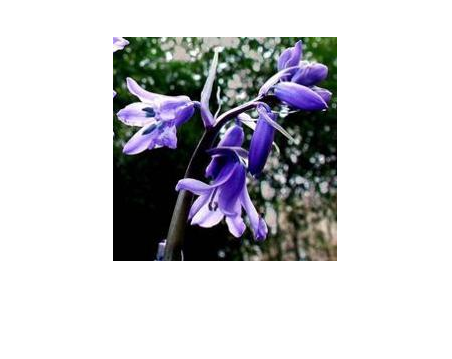

imshow(image)

new_size=imresize(image,[224,224]);
imshow(new_size)

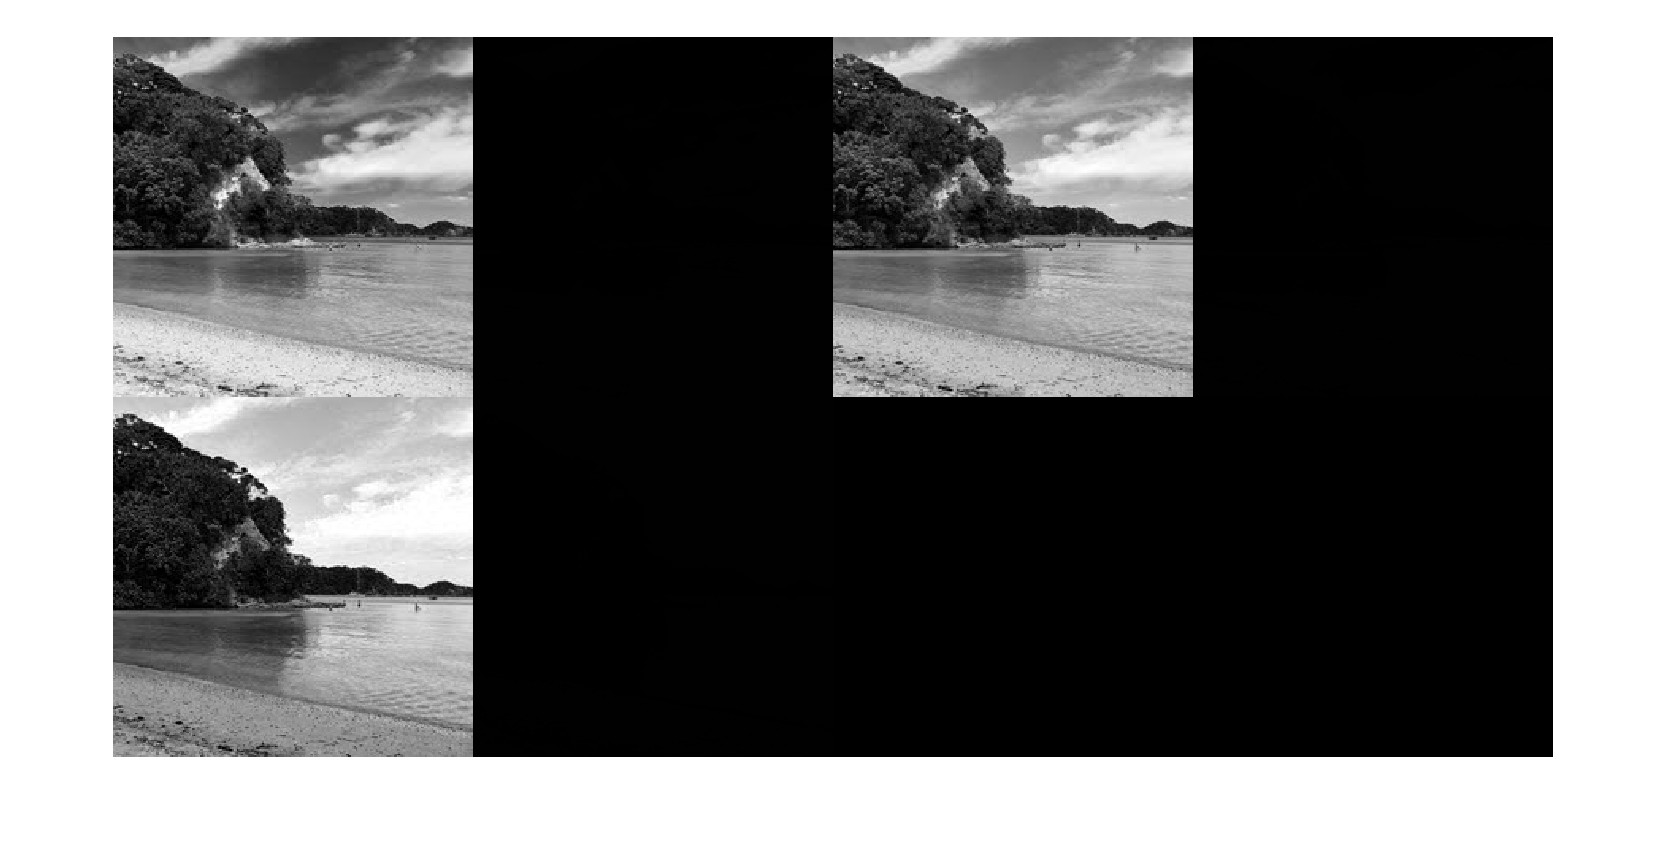

subplot(1,1,1)
a=imread("RandomImages\file01.jpg");
b=mat2gray(a);
montage([a ,b])

model=googlenet;
layers=model.Layers

layers =   144×1 Layer array with layers:

     1   'data'                           Image Input                   224×224×3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2'                   Convolution                   64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU                          ReLU
     4   'pool1-3x3_s2'                   Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1'                    Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce'               Convolution                   64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU                          ReLU
     8   'conv2-3x3'                      Convolution               

% total classes

classes=layers(end).Classes

classes = 1000×1 categorical array
     tench 
     goldfish 
     great white shark 
     tiger shark 
     hammerhead 
     electric ray 
     stingray 
     cock 
     hen 
     ostrich 
     brambling 
     goldfinch 
     house finch 
     junco 
     indigo bunting 
     robin 
     bulbul 
     jay 
     magpie 
     chickadee 
     water ouzel 
     kite 
     bald eagle 
     vulture 
     great grey owl 
     European fire salamander 
     common newt 
     eft 
     spotted salamander 
     axolotl 


new_a=imresize(a,[224,224]);
montage({a,new_a})
pred=classify(model,new_a);
sen1=occlusionSensitivity(model,new_a,"hen")
imshow(sen1)
new=mat2gray(sen1)
imshow(new)
sen2=occlusionSensitivity(model,new_a,pred);

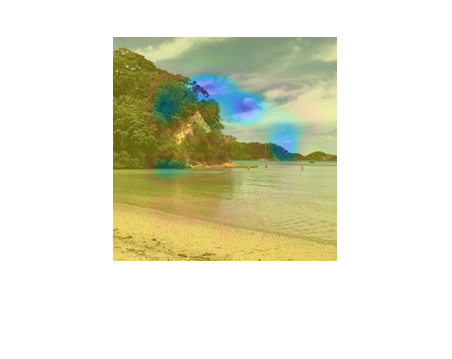

imshow(new_a)
hold on
imagesc(sen1,"AlphaData",0.4)
hold off

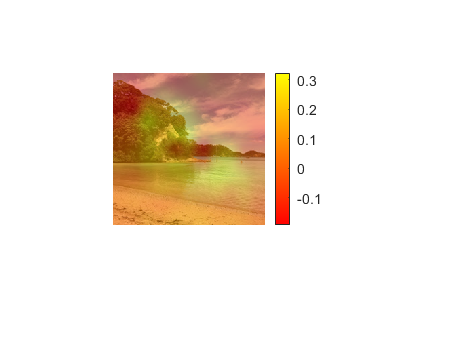

imshow(new_a)
hold on
imagesc(sen2,"AlphaData",0.5)
hold off
colormap autumn
colorbar

a1=a(:,:,1);
a2=a(:,:,2);
a3=a(:,:,3);
a(:,:,4)=a1.*a2.*a3

a = 227×227×4 uint8 array
a(:,:,1) =

    90    90    89    87    85    84    83    82    79    80    82    85    89    90    92    93    89    87    86    89    93    95    95    93    87    88    89    91    92    93    94    96    96    98    99    97    93    92    93    95    99   100   101   101    99    95    92    89    92    89    88    89    90    90    88    87    81    83    78    73    87   116   139   146   147   155   165   172   174   175   183   188   188   188   192   194   196   196   195   194   187   187   189   187   185   179   175   172   168   171   176   183   186   180   170   160   150   151   149   150   147   134   127   134   134   134   140   145   146   157   162   154   138   139   139   131   121   111   107   105    91    91    88    86    81    76    72    69    59    58    59    58    58    59    58    57    56    55    54    53    51    50    49    48    49    49    49    49    50    50    50    50    48    48    48    48    48    48    48    48  

a4=a(:,:,4);
a5=mat2gray(a)

a5 = a5(:,:,1) =

    0.3529    0.3529    0.3490    0.3412    0.3333    0.3294    0.3255    0.3216    0.3098    0.3137    0.3216    0.3333    0.3490    0.3529    0.3608    0.3647    0.3490    0.3412    0.3373    0.3490    0.3647    0.3725    0.3725    0.3647    0.3412    0.3451    0.3490    0.3569    0.3608    0.3647    0.3686    0.3765    0.3765    0.3843    0.3882    0.3804    0.3647    0.3608    0.3647    0.3725    0.3882    0.3922    0.3961    0.3961    0.3882    0.3725    0.3608    0.3490    0.3608    0.3490    0.3451    0.3490    0.3529    0.3529    0.3451    0.3412    0.3176    0.3255    0.3059    0.2863    0.3412    0.4549    0.5451    0.5725    0.5765    0.6078    0.6471    0.6745    0.6824    0.6863    0.7176    0.7373    0.7373    0.7373    0.7529    0.7608    0.7686    0.7686    0.7647    0.7608    0.7333    0.7333    0.7412    0.7333    0.7255    0.7020    0.6863    0.6745    0.6588    0.6706    0.6902    0.7176    0.7294    0.7059    0.6667    0.6275    0.5882    0.5922  

%creating network architecture

input_layer=imageInputLayer([224,224])

input_layer =   ImageInputLayer with properties:

                      Name: ''
                 InputSize: [224 224 1]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: []


conv_layer=convolution2dLayer([3,3],5)

conv_layer =   Convolution2DLayer with properties:

              Name: ''

   Hyperparameters
        FilterSize: [3 3]
       NumChannels: 'auto'
        NumFilters: 5
            Stride: [1 1]
    DilationFactor: [1 1]
       PaddingMode: 'manual'
       PaddingSize: [0 0 0 0]

   Learnable Parameters
           Weights: []
              Bias: []

  Show all properties


relu_layer=reluLayer()

relu_layer =   ReLULayer with properties:

    Name: ''


max_pool=maxPooling2dLayer([2,2])

max_pool =   MaxPooling2DLayer with properties:

                   Name: ''
    HasUnpoolingOutputs: 0
             NumOutputs: 1
            OutputNames: {'out'}

   Hyperparameters
               PoolSize: [2 2]
                 Stride: [1 1]
            PaddingMode: 'manual'
            PaddingSize: [0 0 0 0]


% mlp start
connect=fullyConnectedLayer(5)

connect =   FullyConnectedLayer with properties:

          Name: ''

   Hyperparameters
     InputSize: 'auto'
    OutputSize: 5

   Learnable Parameters
       Weights: []
          Bias: []

  Show all properties


soft=softmaxLayer()

soft =   SoftmaxLayer with properties:

    Name: ''


clasify_layer=classificationLayer()

clasify_layer =   ClassificationOutputLayer with properties:

            Name: ''
         Classes: 'auto'
      OutputSize: 'auto'

   Hyperparameters
    LossFunction: 'crossentropyex'



% final layrer
new_arch=[input_layer;conv_layer;relu_layer;max_pool;connect;soft;clasify_layer]

new_arch =   7×1 Layer array with layers:

     1   ''   Image Input             224×224×1 images with 'zerocenter' normalization
     2   ''   Convolution             5 3×3 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   ReLU                    ReLU
     4   ''   Max Pooling             2×2 max pooling with stride [1  1] and padding [0  0  0  0]
     5   ''   Fully Connected         5 fully connected layer
     6   ''   Softmax                 softmax
     7   ''   Classification Output   crossentropyex

%new_store=imageDatastore("bluebell\","IncludeSubfolders",true,"LabelSource","foldernames")

net=googlenet

net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


net.Layers

ans =   144×1 Layer array with layers:

     1   'data'                           Image Input                   224×224×3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2'                   Convolution                   64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU                          ReLU
     4   'pool1-3x3_s2'                   Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1'                    Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce'               Convolution                   64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU                          ReLU
     8   'conv2-3x3'                      Convolution                  

layers=[imageInputLayer([224,224,3]); convolution2dLayer([3,3],20);reluLayer();maxPooling2dLayer([3,3]); fullyConnectedLayer(1,"Name","cc");softmaxLayer()
    classificationLayer()]

layers =   7×1 Layer array with layers:

     1   ''     Image Input             224×224×3 images with 'zerocenter' normalization
     2   ''     Convolution             20 3×3 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''     ReLU                    ReLU
     4   ''     Max Pooling             3×3 max pooling with stride [1  1] and padding [0  0  0  0]
     5   'cc'   Fully Connected         1 fully connected layer
     6   ''     Softmax                 softmax
     7   ''     Classification Output   crossentropyex

algo=trainingOptions("adam","InitialLearnRate",0.0004)

algo =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.9000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 4.0000e-04
             LearnRateSchedule: 'none'
           LearnRateDropFactor: 0.1000
           LearnRateDropPeriod: 10
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: Inf
                     MaxEpochs: 30
                 MiniBatchSize: 128
                       Verbose: 1
              VerboseFrequency: 50
                ValidationData: []
           ValidationFrequency: 50
            ValidationPatience: Inf
                       Shuffle: 'once'
                CheckpointPath: ''
          ExecutionEnvironment: 'auto'
                    WorkerLoad: []
                     OutputFcn: []
                         Plots: 'none'
   

%new_store=imageDatastore("bluebell\","IncludeSubfolders",true,"LabelSource","foldernames")
%train_arch=trainNetwork(new_store,layers,algo)
%pred=classify(layers,new_store,algo)


ds =   ImageDatastore with properties:

                       Files: {
                              ' ...\deeplearning_course_files\bluebell\image_0241.jpg';
                              ' ...\deeplearning_course_files\bluebell\image_0242.jpg';
                              ' ...\deeplearning_course_files\bluebell\image_0243.jpg'
                               ... and 77 more
                              }
                     Folders: {
                              ' ...\mtlb (1)\deeplearning_course_files\deeplearning_course_files\bluebell'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


b = 224×224×3 uint8 array
b(:,:,1) =

   103   103   103   103   103   103   103   103   105   105   106   107   108   108   107   107   108   108   108   108   107   107   107   107   108   108   109   110   110   110   110   110   110   110   108   110   110   113   114   115   114   116   118   121   123   124   122   122   121   119   116   113   113   108   104   100    95    89    81    72    66    60    55    51    48    47    52    61    66    66    71    79    63    67    85   114   135   133   116   101    90    85    81    80    79    78    84    92   100   106   113   118   120   121   121   121   122   122   121   120   120   119   118   118   119   119   119   119   119   119   119   119   121   121   122   123   123   124   125   125   126   126   126   127   127   128   128   127   126   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   121   121   120   119   118   118   117   117   114   114   114   113   113   112   112   111  

ans = 224×224×3 uint8 array
ans(:,:,1) =

   103   103   103   103   103   103   103   103   105   105   106   107   108   108   107   107   108   108   108   108   107   107   107   107   108   108   109   110   110   110   110   110   110   110   108   110   110   113   114   115   114   116   118   121   123   124   122   122   121   119   116   113   113   108   104   100    95    89    81    72    66    60    55    51    48    47    52    61    66    66    71    79    63    67    85   114   135   133   116   101    90    85    81    80    79    78    84    92   100   106   113   118   120   121   121   121   122   122   121   120   120   119   118   118   119   119   119   119   119   119   119   119   121   121   122   123   123   124   125   125   126   126   126   127   127   128   128   127   126   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   121   121   120   119   118   118   117   117   114   114   114   113   113   112   112   1

ans = 80×1 cell array
    {224×224×3 uint8}
    {224×224×3 uint8}
    {224×224×3 uint8}
    {224×224×3 uint8}
    {224×224×3 uint8}
    {224×224×3 uint8}
    {224×224×3 uint8}
    {224×224×3 uint8}
    {224×224×3 uint8}
    {224×224×3 uint8}
    {224×224×3 uint8}
    {224×224×3 uint8}
    {224×224×3 uint8}
    {224×224×3 uint8}
    {224×224×3 uint8}
    {224×224×3 uint8}


%---------------deep learning  matlab revision------------------

img=readimage(flowers_ds,5);
net=googlenet

net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


layers=net.Layers

layers =   144×1 Layer array with layers:

     1   'data'                           Image Input                   224×224×3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2'                   Convolution                   64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU                          ReLU
     4   'pool1-3x3_s2'                   Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1'                    Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce'               Convolution                   64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU                          ReLU
     8   'conv2-3x3'                      Convolution               

p=layers(14).Name

p = 'inception_3a-3x3_reduce'

actvn=activations(net,img,"conv1-7x7_s2")

actvn = 112×112×64 single array
actvn(:,:,1) =

  -27.8528 -101.7855  -69.1058  -26.2534  -25.9534    3.0986   16.5460   -4.4288  -21.5270   -0.0697    4.9721    0.4160   16.3214    7.0835   15.1734   15.8911    0.4809  -23.9317    0.8493   15.5674    8.9855   33.4017   -0.1118  -10.3555  -13.3983  -37.1427    2.2724   -6.4401   19.3039    2.8316   -0.9235   31.5403   27.2752  -13.5582    0.1215  -15.5834  -30.8909   -3.3533  -19.8485   -8.7171    7.7550   33.9022   15.1116   14.4387    9.1391    7.6987  -12.8410  -12.3662  -12.7112  -14.3316  -13.5063   -7.2556  -23.5777   -6.2379   -9.3444   -0.6556   24.1824    9.4518    2.1345  -10.2175  -12.4102  -16.0797  -29.2452  -21.9257  -22.4932   29.6022  -14.8841   -1.8590  -27.2650  -44.6437  -24.4464    7.4669   13.2845    5.6370  -15.6694   -4.3283  -27.0230   -6.3961   -0.9414   -8.4776  -42.3761  -34.3103  -30.4752  -36.1331    5.5711    9.8856   35.7933   29.7557  -22.0919   -0.9632   82.8026  105.4345   69.3515   -3.8260  -38.0711  

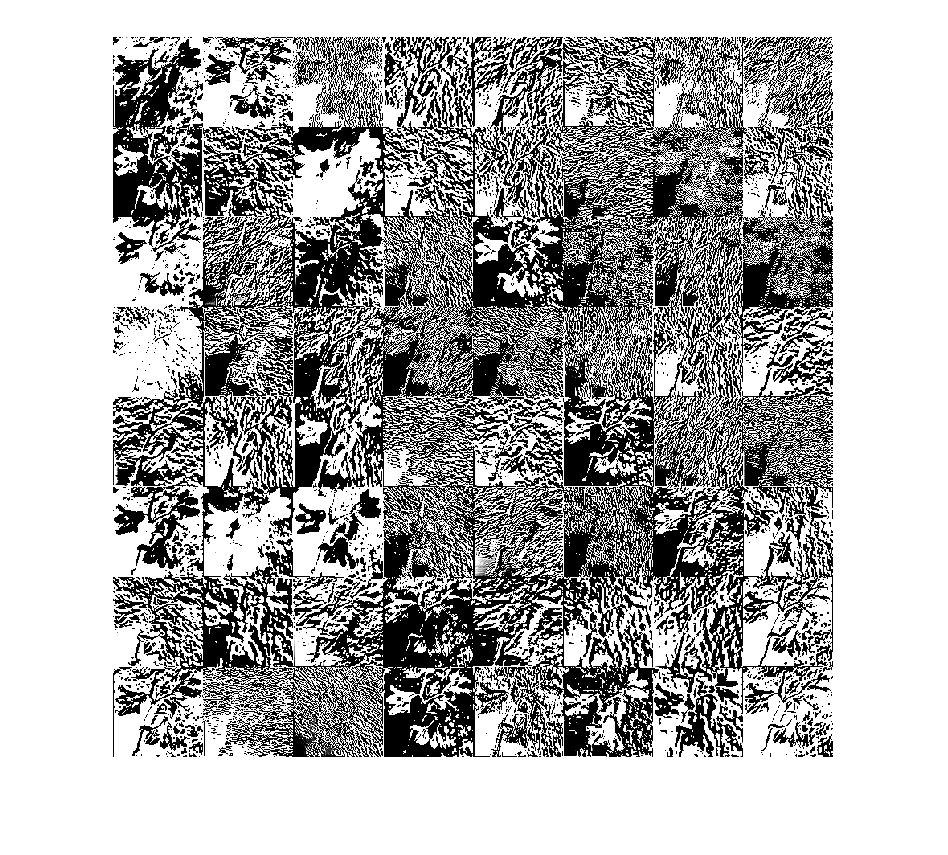

montage(actvn);

actvn1=activations(net,img,p)

actvn1 = 28×28×96 single array
actvn1(:,:,1) =

   47.2601   18.8154   20.4469   11.3180   18.0549   -8.4760    1.7492  -20.5769   -7.5291   -2.9691  -28.1470  -14.5507  -30.1324  -38.6495  -50.8287  -28.8590    1.7987  -24.5898    8.5856   37.6965    6.6887  -27.5731    8.3991   -4.4903  -16.2453   -3.1677    3.4550    7.8680
   60.1188    1.3531    1.7971   54.7675   35.5532   18.0576   20.0724  -78.5032  -99.3475    4.3662  -19.8632  -33.1825    8.7564   61.9393   36.2556   14.9086  -45.7211  -60.1559   48.9429   62.0518    2.3297  -68.6835  -45.2371  -22.5331  -20.6360   16.7468   47.3674  -13.4175
   55.2273   -4.0278    0.0975   73.5941   22.8537    5.2985   -3.6276  -84.6556 -127.8883  -11.8898   10.4187   57.3949   35.3779   76.1765   41.7268   42.1740  -27.3781  -69.0634  -16.9415   -4.8196   52.9505   74.1360   14.6832  -29.6888  -36.4573  -15.5324   47.0376   10.2208
   43.8277   57.7319   35.0391   61.3755   42.2170    0.5049   27.5928   34.7845   30.1323   20.9794   28.478

montage(actvn)

pool_1_norml=layers(2) 

pool_1_norml =   Convolution2DLayer with properties:

              Name: 'conv1-7x7_s2'

   Hyperparameters
        FilterSize: [7 7]
       NumChannels: 3
        NumFilters: 64
            Stride: [2 2]
    DilationFactor: [1 1]
       PaddingMode: 'manual'
       PaddingSize: [3 3 3 3]

   Learnable Parameters
           Weights: [7×7×3×64 single]
              Bias: [1×1×64 single]

  Show all properties


norm_actn=mat2gray(actvn)

norm_actn = norm_actn(:,:,1) =

    0.4976    0.4888    0.4927    0.4978    0.4979    0.5014    0.5030    0.5005    0.4984    0.5010    0.5016    0.5010    0.5029    0.5018    0.5028    0.5029    0.5010    0.4981    0.5011    0.5029    0.5021    0.5050    0.5010    0.4997    0.4994    0.4965    0.5013    0.5002    0.5033    0.5013    0.5009    0.5048    0.5043    0.4994    0.5010    0.4991    0.4973    0.5006    0.4986    0.4999    0.5019    0.5051    0.5028    0.5027    0.5021    0.5019    0.4994    0.4995    0.4995    0.4993    0.4994    0.5001    0.4982    0.5002    0.4999    0.5009    0.5039    0.5021    0.5012    0.4998    0.4995    0.4991    0.4975    0.4984    0.4983    0.5045    0.4992    0.5008    0.4977    0.4956    0.4981    0.5019    0.5026    0.5017    0.4991    0.5005    0.4977    0.5002    0.5009    0.5000    0.4959    0.4969    0.4973    0.4966    0.5017    0.5022    0.5053    0.5046    0.4983    0.5009    0.5109    0.5136    0.5093    0.5005    0.4964    0.5019    0.49

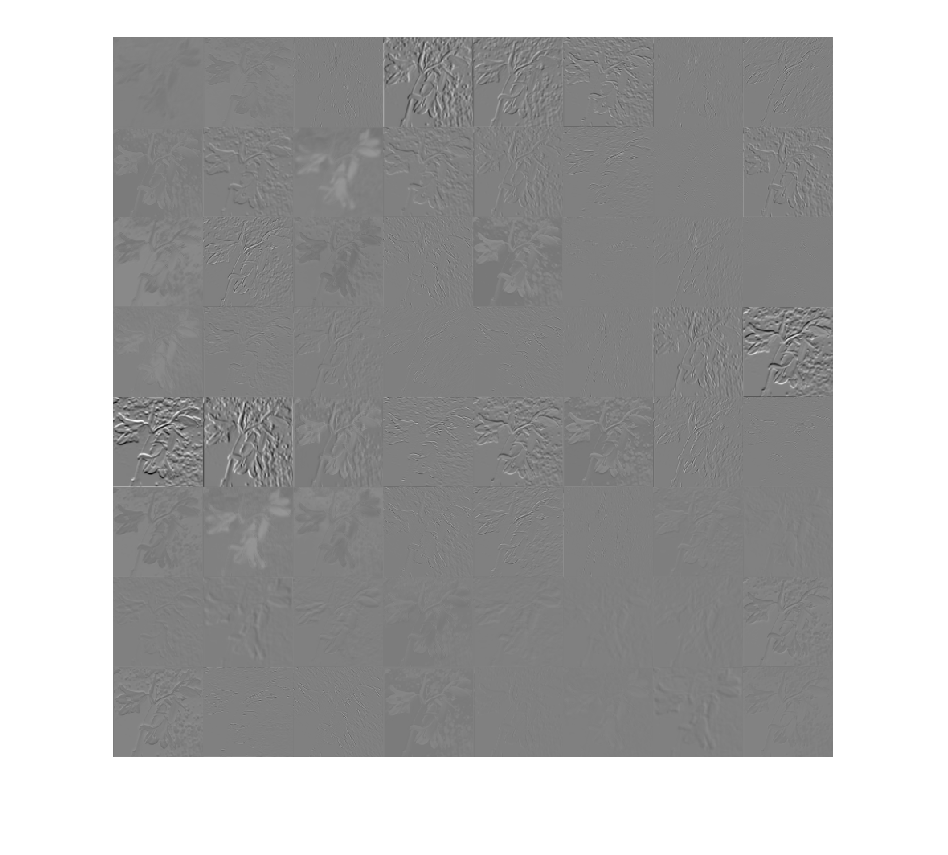

montage(norm_actn)

classses=net.Layers(end).Classes

classses = 1000×1 categorical array
     tench 
     goldfish 
     great white shark 
     tiger shark 
     hammerhead 
     electric ray 
     stingray 
     cock 
     hen 
     ostrich 
     brambling 
     goldfinch 
     house finch 
     junco 
     indigo bunting 
     robin 
     bulbul 
     jay 
     magpie 
     chickadee 
     water ouzel 
     kite 
     bald eagle 
     vulture 
     great grey owl 
     European fire salamander 
     common newt 
     eft 
     spotted salamander 
     axolotl 


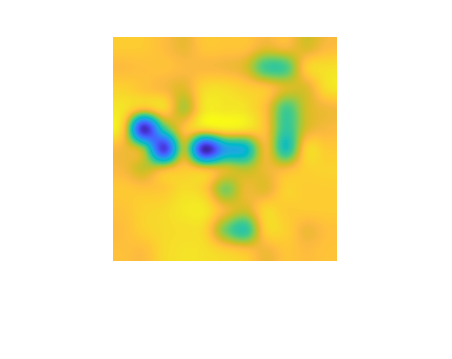

p=occlusionSensitivity(net,img,classses(4));
imshow(img)
hold on
imagesc(p)
hold off

imshow(img)

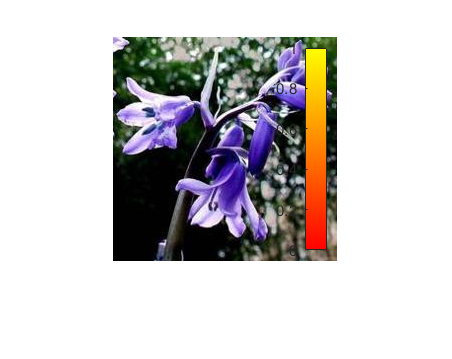

colorbar east
colormap autumn

%------------------------------------------------------------
MY_LAYERS=[imageInputLayer([224,224,3]);
convolution2dLayer([5,5],40);
reluLayer();
maxPooling2dLayer([4,4]);
fullyConnectedLayer(1);
softmaxLayer();
classificationLayer()]

MY_LAYERS =   7×1 Layer array with layers:

     1   ''   Image Input             224×224×3 images with 'zerocenter' normalization
     2   ''   Convolution             40 5×5 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   ReLU                    ReLU
     4   ''   Max Pooling             4×4 max pooling with stride [1  1] and padding [0  0  0  0]
     5   ''   Fully Connected         1 fully connected layer
     6   ''   Softmax                 softmax
     7   ''   Classification Output   crossentropyex

options=trainingOptions("adam","Plots","training-progress","MaxEpochs",5,"InitialLearnRate",0.0005)

options =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.9000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 5.0000e-04
             LearnRateSchedule: 'none'
           LearnRateDropFactor: 0.1000
           LearnRateDropPeriod: 10
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: Inf
                     MaxEpochs: 5
                 MiniBatchSize: 128
                       Verbose: 1
              VerboseFrequency: 50
                ValidationData: []
           ValidationFrequency: 50
            ValidationPatience: Inf
                       Shuffle: 'once'
                CheckpointPath: ''
          ExecutionEnvironment: 'auto'
                    WorkerLoad: []
                     OutputFcn: []
                         Plots: 'trainin

store=imageDatastore("practical\","IncludeSubfolders",true,"LabelSource","foldernames")

store =   ImageDatastore with properties:

                       Files: {
                              ' ...\Desktop\matlab_data_files\practical\bluebell\image_0241.jpg';
                              ' ...\Desktop\matlab_data_files\practical\bluebell\image_0242.jpg';
                              ' ...\Desktop\matlab_data_files\practical\bluebell\image_0243.jpg'
                               ... and 77 more
                              }
                     Folders: {
                              'C:\Users\Adarsh Kumar\Desktop\matlab_data_files\practical'
                              }
                      Labels: [bluebell; bluebell; bluebell ... and 77 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatasto

network=trainNetwork(store,MY_LAYERS,options)

Training on single CPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:29 |      100.00% |  -0.0000e+00 |          0.0005 |


|       5 |           5 |       00:01:36 |      100.00% |  -0.0000e+00 |          0.0005 |
|========================================================================================|


network =   SeriesNetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


data=imageDatastore("bluebell\","IncludeSubfolders",true,"LabelSource","foldernames")

data =   ImageDatastore with properties:

                       Files: {
                              ' ...\deeplearning_course_files\bluebell\image_0241.jpg';
                              ' ...\deeplearning_course_files\bluebell\image_0242.jpg';
                              ' ...\deeplearning_course_files\bluebell\image_0243.jpg'
                               ... and 77 more
                              }
                     Folders: {
                              ' ...\deeplearning_course_files\deeplearning_course_files\bluebell'
                              }
                      Labels: [bluebell; bluebell; bluebell ... and 77 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


%out=classify(data)
%confusionchart(test,predict)

f1=ones(224,224)

f1 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1  

img=imread("Flowers\bluebell\image_0241.jpg")

img = 224×224×3 uint8 array
img(:,:,1) =

   103   103   103   103   103   103   103   103   105   105   106   107   108   108   107   107   108   108   108   108   107   107   107   107   108   108   109   110   110   110   110   110   110   110   108   110   110   113   114   115   114   116   118   121   123   124   122   122   121   119   116   113   113   108   104   100    95    89    81    72    66    60    55    51    48    47    52    61    66    66    71    79    63    67    85   114   135   133   116   101    90    85    81    80    79    78    84    92   100   106   113   118   120   121   121   121   122   122   121   120   120   119   118   118   119   119   119   119   119   119   119   119   121   121   122   123   123   124   125   125   126   126   126   127   127   128   128   127   126   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   121   121   120   119   118   118   117   117   114   114   114   113   113   112   112   1

img=im2gray(img)

img = 224×224 uint8 matrix
   102   102   102   102   102   102   102   102   104   104   105   106   107   107   106   106   108   108   108   108   107   107   107   107   108   108   109   110   110   110   110   110   107   107   107   109   110   113   115   116   117   119   122   125   127   128   128   128   127   125
   101   101   101   101   101   101   101   101    98    98    99   100   101   100   100   100   105   105   105   105   105   104   104   104   105   105   106   107   108   108   107   107   105   106   106   107   109   111   113   114   116   118   121   124   126   127   128   128   127   124
    98    98    98    98    98    98    98    98    96    97    98    99    99    99    99    98   100   101   101   101   101   101   101   101   101   102   103   104   104   104   104   103   103   103   104   105   106   108   110   111   113   115   119   122   125   126   127   127   125   123
    94    94    94    94    94    94    94    94    94    95    96    

size(img)

ans =    224   224


f1(:,[1:10,200:224])=zeros(224,35)

f1 =      0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1  

new=double(img)*f1

new =            0           0           0           0           0           0           0           0           0           0       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139       24139
           0           0           0           0           0           0           0           0           0           0       24030       24030       24030       24030       24030       24030       24030       24030       24030       24030       24030       24030       24030       24030       24030       24030       24030       24030       24030       24030       24030       24030       24

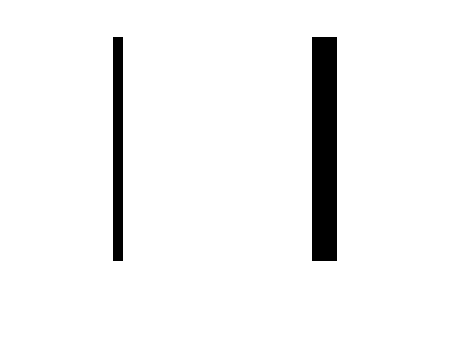

imshow(new)

p=conv2(f1,img)

p =            0           0           0           0           0           0           0           0           0           0         102         204         306         408         510         612         714         816         920        1024        1129        1235        1342        1449        1555        1661        1769        1877        1985        2093        2200        2307        2414        2521        2629        2737        2846        2956        3066        3176        3286        3396        3503        3610        3717        3826        3936        4049        4164        4280
           0           0           0           0           0           0           0           0           0           0         203         406         609         812        1015        1218        1421        1624        1826        2028        2232        2438        2646        2853        3059        3265        3478        3691        3904        4117        4329        4540        475

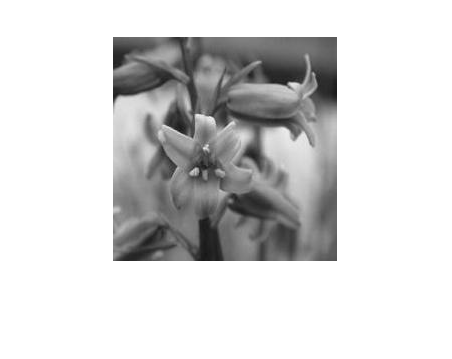

imshow(img)

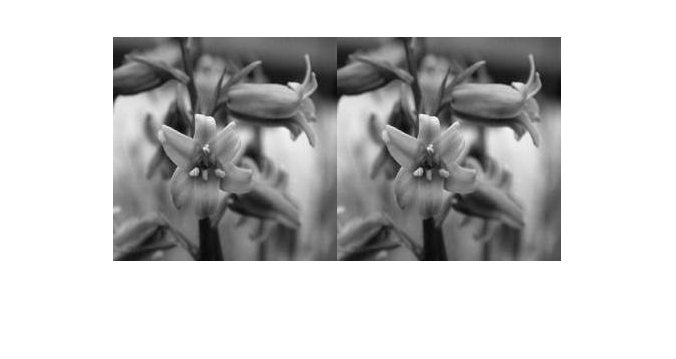

imshowpair(img,img,"montage")

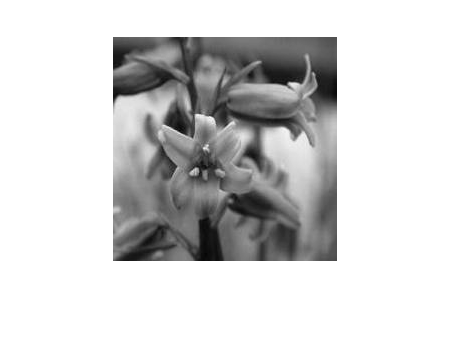

imshow(img,[])                          % [] show imshow must plot with range of min and max pixel range.


[train,val,test]=splitEachLabel(date,0.8,0.1);
options=trainingOptions("adam","Plots","training-progress","ValidationData",val,"MaxEpochs",4,"InitialLearnRate",00.004)
impixel(image_0241)

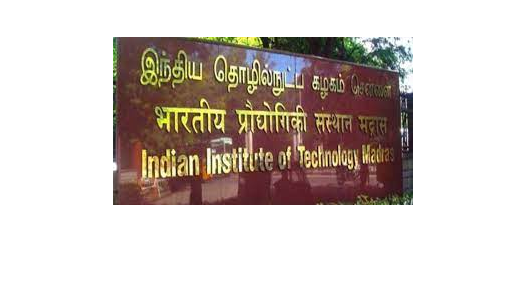

a=imread("C:\Users\Adarsh Kumar\Desktop\static\images.jpg");
imshow(a)

b=im2gray(a)

b = 168×300 uint8 matrix
   148   125    97   107    95    90    77    91    81    81    80    80    79    79    79    78    77    77    78    78    79    79    79    79    79    79    79    79    78    78    77    77    81    80    79    78    77    75    74    74    78    78    77    76    75    74    74    73    67    67
   114    94    83   105    91    85    72    77    80    80    80    79    79    78    78    78    77    77    77    78    78    79    79    79    79    79    79    78    78    77    77    77    79    78    77    76    75    74    73    73    78    77    77    76    75    74    73    73    67    67
    90    73    82   118    99    93    82    76    80    79    79    79    78    78    77    77    76    76    76    77    77    78    78    78    78    78    78    77    77    76    76    76    75    75    75    74    73    73    72    72    77    77    76    75    74    73    73    72    68    68
    85    68    87   127   101    96    87    77    79    78    78    78

filter=ones(3,3)

filter =      1     1     1
     1     1     1
     1     1     1


new_img=filter2(filter,b)

new_img =    481   661   611   578   573   510   492   478   490   482   480   477   474   472   470   467   464   463   465   468   471   473   474   474   474   474   473   471   468   465   463   468   472   474   468   462   455   448   443   450   458   465   461   456   450   445   441   427   414   402
   644   906   884   877   883   784   743   716   725   720   717   713   709   705   702   697   693   691   694   698   703   706   708   708   708   708   706   703   698   694   691   695   698   699   692   684   675   666   660   671   684   695   689   681   672   665   659   640   622   606
   524   776   837   893   915   806   745   710   706   713   710   707   703   698   695   690   687   684   687   690   696   699   702   702   702   702   699   696   690   687   684   683   681   678   674   669   664   659   656   667   679   689   683   675   666   659   653   638   624   612
   474   729   832   911   928   808   741   705   693   704   701   698   694   689   

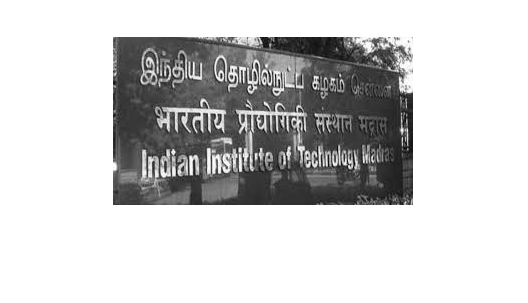

imshow(b)

imshow(new_img)


new_img

new_img =    481   661   611   578   573   510   492   478   490   482   480   477   474   472   470   467   464   463   465   468   471   473   474   474   474   474   473   471   468   465   463   468   472   474   468   462   455   448   443   450   458   465   461   456   450   445   441   427   414   402
   644   906   884   877   883   784   743   716   725   720   717   713   709   705   702   697   693   691   694   698   703   706   708   708   708   708   706   703   698   694   691   695   698   699   692   684   675   666   660   671   684   695   689   681   672   665   659   640   622   606
   524   776   837   893   915   806   745   710   706   713   710   707   703   698   695   690   687   684   687   690   696   699   702   702   702   702   699   696   690   687   684   683   681   678   674   669   664   659   656   667   679   689   683   675   666   659   653   638   624   612
   474   729   832   911   928   808   741   705   693   704   701   698   694   689   

b

b = 168×300 uint8 matrix
   148   125    97   107    95    90    77    91    81    81    80    80    79    79    79    78    77    77    78    78    79    79    79    79    79    79    79    79    78    78    77    77    81    80    79    78    77    75    74    74    78    78    77    76    75    74    74    73    67    67
   114    94    83   105    91    85    72    77    80    80    80    79    79    78    78    78    77    77    77    78    78    79    79    79    79    79    79    78    78    77    77    77    79    78    77    76    75    74    73    73    78    77    77    76    75    74    73    73    67    67
    90    73    82   118    99    93    82    76    80    79    79    79    78    78    77    77    76    76    76    77    77    78    78    78    78    78    78    77    77    76    76    76    75    75    75    74    73    73    72    72    77    77    76    75    74    73    73    72    68    68
    85    68    87   127   101    96    87    77    79    78    78    78